# 基于H∞鲁棒控制的主动降噪耳罩

## 理论背景

### A. H∞鲁棒控制理论

本节简要回顾了H∞鲁棒控制理论。以下推导包含了大量的数学定义和结果。由于H∞理论在大量控制文献中均有详细论述[7-12]，因此这里只列出在ANC算法开发中所需的关键内容，其余部分不再赘述。由于系统模型是通过离散时间域的参数辨识方法获得的，本文仅介绍离散时间H∞算法。

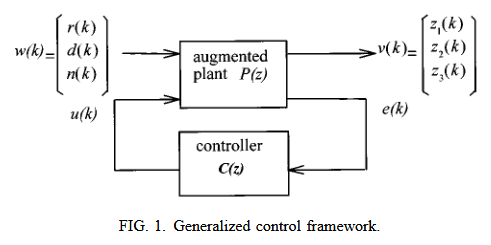

在现代控制理论中，所有控制结构都可以通过广义控制框架来描述，如图1所示。该框架包含一个控制器C(z)和一个增广对象P(z)。受控变量v(k)对应于各种控制目标z₁(k)、z₂(k)、z₃(k)，而外部输入w(k)包括参考信号r(k)、扰动d(k)和噪声n(k)。信号u(k)和e(k)分别为施加到对象的控制输入和从对象测得的输出。

一般的输入-输出关系可表示为：


$$\left\lbrack \begin{array}{c}
V\left(z\right)\\
E\left(z\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
P_{11} \left(z\right) & P_{12} \left(z\right)\\
P_{21} \left(z\right) & P_{22} \left(z\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
W\left(z\right)\\
U\left(z\right)
\end{array}\right\rbrack =P_{\gamma \;} \left(z\right)\left\lbrack \begin{array}{c}
W\left(z\right)\\
U\left(z\right)
\end{array}\right\rbrack$$


其中，子矩阵$P_{\textrm{ij}} \left(z\right),i,j=1,2$是增广对象$P_{\gamma \;} \left(z\right)$的兼容分块（compatible partitions），符号均为Z变换后的变量。H∞控制的基本思想是最小化传递函数$T_{\textrm{vw}} \left(z\right)$（v(k)与w(k)之间）的无穷范数，它可通过线性分式变换（LFT）表示为：


$$T_{vw}(z) = \mathrm{LFT}(P_\gamma(z), C(z)) = P_{11}(z) + P_{12}(z)C(z)[I - P_{22}(z)C(z)]^{-1}P_{21}(z) $$


因此，最优H∞问题的数学表述为：


$$\min_{C(z)} \|T_{vw}(z)\|\infty = \min_{C(z)} \sup_{0 \leq \theta < 2\pi} \|T_{vw}(e^{j\theta})\|$$


然而，寻找最优解通常非常困难，因此实际中常采用可解析获得的次优解。这就形成了所谓的标准H∞问题：寻找C(z)，使得$\|T_{\textrm{vw}} \left(z\right){\|}_{\infty \;} <1$。由于控制问题被纳入广义框架，许多H∞算法都可以综合出最优控制器。

现有算法大致分为两类：**模型匹配算法（Model Matching Algorithms, 1984年方法）**和**两Riccati方程算法（Two-Riccati Equation Algorithms, 1988年方法）**。本研究采用后者，该方法无需像前者那样进行一系列因式分解，因此在处理高阶（声学）对象时可减少数值问题。由于该算法包含大量标准控制文献中的代数定义和表达式，本文不再赘述，详情可参考文献12。

### B 模型匹配方法（1984 Approach）

1980s初，Doyle等人首次把 H∞ 控制问题形式化。Zames、Helton 等早期工作将鲁棒/灵敏度最小化（H∞）问题表述为频域的最坏增益最小化问题。1980s 早期的解法以 **传递函数与因子分解** 为主，目标是找一个控制器 $K\left(s\right)$ 使闭环某个传递矩阵 $T_{\textrm{zw}} \left(s\right)$ 在 H∞ 范数意义下最小（或小于某阈 γ）。该方法常被称作 *model-matching* 或 *factorization-based H∞ method。*

1984 年在Honeywell的ONR研讨会上，提出了一种以"模型匹配 (model matching)"为核心的算法。其基本思想是，把H∞ 优化问题转化为一个 **有理函数的逼近问题**，即要求找到一个控制器，使得某个传递函数尽量接近给定的目标函数。它依赖 **一连串的因子分解（chain of factorizations）** 和算子理论工具（如 Nehari 定理、Glover-Millman 类型逼近理论等）。它提供了 H∞ 问题的最早完整解法框架。

- 优点：为 H∞ 理论奠定频域与算子理论基础；在某些解析场景下能给出明确的逼近解。

- 缺点：对高阶系统/噪声很容易出现数值问题；实现复杂；不如状态空间方法在工程上易用。

### C DGKF 两Riccati方程方法（1988 Approach）

1988/1989 年 Doyle、Glover、Khargonekar、Francis（DGKF）等把 H∞ 问题带入**状态空间，**给出"标准 H∞ 问题"的**状态空间充分必要条件**：控制器存在当且仅当两个分别与控制方向和估计方向相关的代数 Riccati 方程存在稳定的解，且两解的某个谱半径条件满足。其基本思想是，把 H∞ 控制问题转化为 **两个耦合代数 Riccati 方程 (AREs)** 的解。在给定广义被控系统$P$的情况下，通过求解两个Riccati方程（一个用于控制方向，另一个用于估计方向），构造出满足H∞ 性能指标的控制器。它不需要复杂的因子分解，而是直接在状态空间内计算。**白明宪所选用的方法正是1988方法，因为它不需要像前者那样进行一连串因子分解，因此在处理高阶声学系统时能避免数值问题。**

以连续时间状态空间形式为例：


$$\dot{x}=Ax+B_1w+B_2u\\
z=C_1x+D_{11}w+D_{12}u\\
y=C_2x+D_{21}w+D_{22}u$$


**目标**：求一个动态控制器（状态空间形式）使闭环从 w 到 z 的传递矩阵的 H∞ 范数小于 γ。**DGKF 将问题转化为求解两条代数 Riccati 方程（ARE）**，并给出构造控制器的明确代数表达式；存在性等价于这两 ARE 的 stabilizing 解存在且满足额外的谱半径条件。

- 优点：状态空间形式、可数值实现、对高阶系统较稳定、容易与现代数值代数库结合，成为 MathWorks 等工具箱实现的基础。

- 缺点：需要可控/可观/正则性等假设；构造出的控制器阶次等于对象阶次（可能较高），但可采用降阶或固定结构调优方法（见后）。

### D 标准问题定义

记$P_1 \left(z\right)$为噪声主通路，$P_2 \left(z\right)$为次通路（被控对象），我们设计 H∞ 控制器的方法是对分别对灵敏度函数$\tilde{S} \left(z\right)$，控制输入$U\left(z\right)$，互补灵敏度函数$\tilde{T} \left(z\right)$分别使用$W_1 \left(z\right),W_2 \left(z\right),W_3 \left(z\right)$加权。

一方面，干扰抑制/跟踪性能的标称性能条件（nominal performance condition）要求${\left\|\tilde{S} \left(z\right)W_1 \left(z\right)\right\|}_{\infty \;} <1$；而应对系统干扰（system stability）和模型不确定性（model uncertainties）的系统稳定性，由小增益定理要求${\left\|\tilde{T} \left(z\right)W_3 \left(z\right)\right\|}_{\infty \;} <1$。

在通常的回路成型设计中，$W_1 \left(z\right)$通常被选为低通函数而$W_3 \left(z\right)$被选为高通函数。$S\left(z\right)$与$T\left(z\right)$之间的权衡，以及水床效应共同决定了反馈设计的性能以及鲁棒性。这种经典的权衡就产生了所谓的混合灵敏度（mixed sensitivity problem）问题，它也是控制器同时实现标称性能和鲁棒稳定性的充要条件。

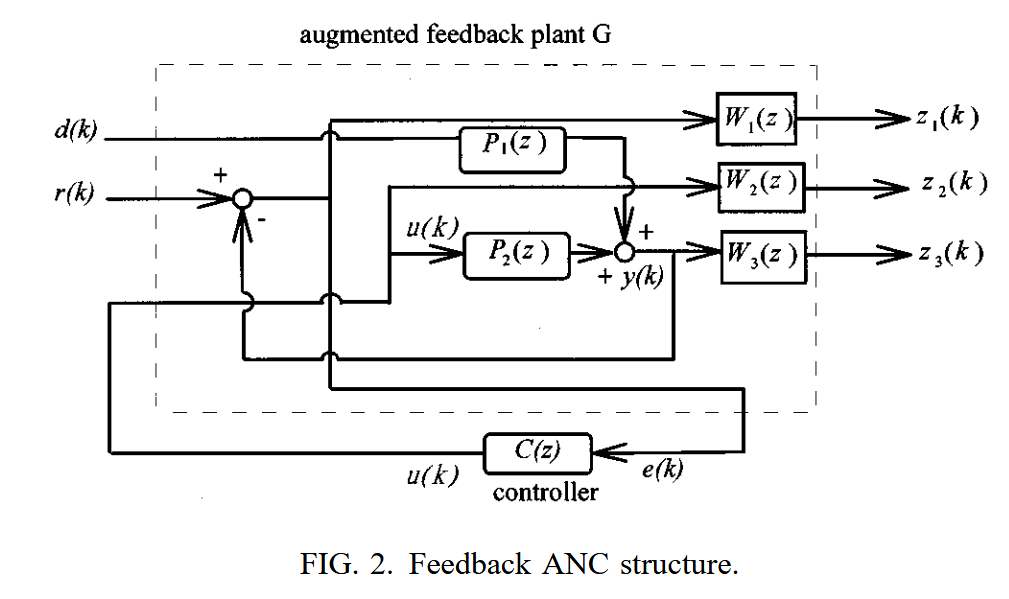

在H∞ 理论里，混合灵敏度问题就是要求：${\left\|\left\lbrack \begin{array}{c}
W_1 S\\
W_2 R\\
W_3 T
\end{array}\right\rbrack \right\|}_{\infty \;} <1$，其中$W_1$为低频性能权重，$W_2$为控制权重，而$W_3$则为高频鲁棒性权重，$R=S\;C$对应控制输入。这在ANC问题中分别对应于噪声抑制、控制信号约束以及闭环稳定裕度这三个目标。ANC 的物理需求和混合灵敏度问题的数学结构是 **一一对应** 的。

文章给出了增广系统的构造：$\left\lbrack \begin{array}{c}
Z_1 \left(z\right)\\
Z_2 \left(z\right)\\
Z_3 \left(z\right)\\
E\left(z\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
W_1 \left(z\right) & -W_1 \left(z\right)P_2 \left(z\right)\\
0 & W_2 \left(z\right)\\
0 & W_3 \left(z\right)P_2 \left(z\right)\\
1 & -P_2 \left(z\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
D\left(z\right)\\
U\left(z\right)
\end{array}\right\rbrack$,其中$D\left(z\right)$是外部扰动，$U\left(z\right)$是控制输入，$E\left(z\right)$是可测输出（麦克风信号）；$Z_1 \left(z\right),Z_2 \left(z\right),Z_3 \left(z\right)$是性能输出的不同构成（对应于加权的灵敏度、控制输入与互补灵敏度），通过引入权重W1, W2, W3，ANC问题（本质是混合灵敏度问题）被改写为一个 **标准 H∞ 控制问题**。

## 1 根据表格参数构建被控对象

clear; close all; clc;
% 1. 构建被控对象的传递函数
z = [-3.0841, 1.0320, -0.4387, 0.0034];
p = [0.6612+0.3483i, 0.6612-0.3483i, -0.4426+0.3324i, -0.4426-0.3324i];
k = 0.3921;
P_tf = zpk(z, p, k);

% 权重函数定义 (基于MSBai1977论文)
s = tf('s');
% 方案1: 增强W3的高频滚降
W3_inv = 2*(0.6554*s + 2592) / (s + 5000);  % 增大极点频率
% 方案2: 放松W1的低频要求  
W1_inv = (4*s^2 + 2500*s + 1.027e7) / (s^2 + 7969*s + 8.542e6);  % 增大系数
W1 = 1/W1_inv;
W3 = 1/W3_inv;
% 目标：在 200-800 Hz 提供 ~15 dB 抑制
Smax = 10^(-15/20);            % 约 0.178
W1_low = 1/Smax;               % 约 5.62
wb = 2*pi*400;                 % 以 400 Hz 为设计带宽中心（rad/s）
eps = 0.01;                    % W1 在高频处较小
W1 = makeweight(W1_low, wb, eps);
W1_inv = 1/W1;
% W3: 在高频 (>= 1kHz) 约束互补灵敏度，使 T_max ~0.1 (即 20 dB 保持)
Tmax = 0.1;
W3_high = 1/Tmax;              % 10
wh = 2*pi*1000;                % 高频交叉点 1 kHz
W3 = makeweight(eps, wh, W3_high);  % 低频小，高频大 -> highpass-like
W3_inv = 1/W3;

% 分析系统特性
rhp_zeros = z(real(z) > 0);
rhp_poles = p(real(p) > 0);
if ~isempty(rhp_zeros)
    fprintf('⚠️  系统包含%d个右半平面零点，将限制可达性能\n', length(rhp_zeros));
end

⚠️  系统包含2个右半平面零点，将限制可达性能


if ~isempty(rhp_poles)
    fprintf('⚠️  系统包含%d个右半平面极点，系统不稳定\n', length(rhp_poles));
end

⚠️  系统包含2个右半平面极点，系统不稳定


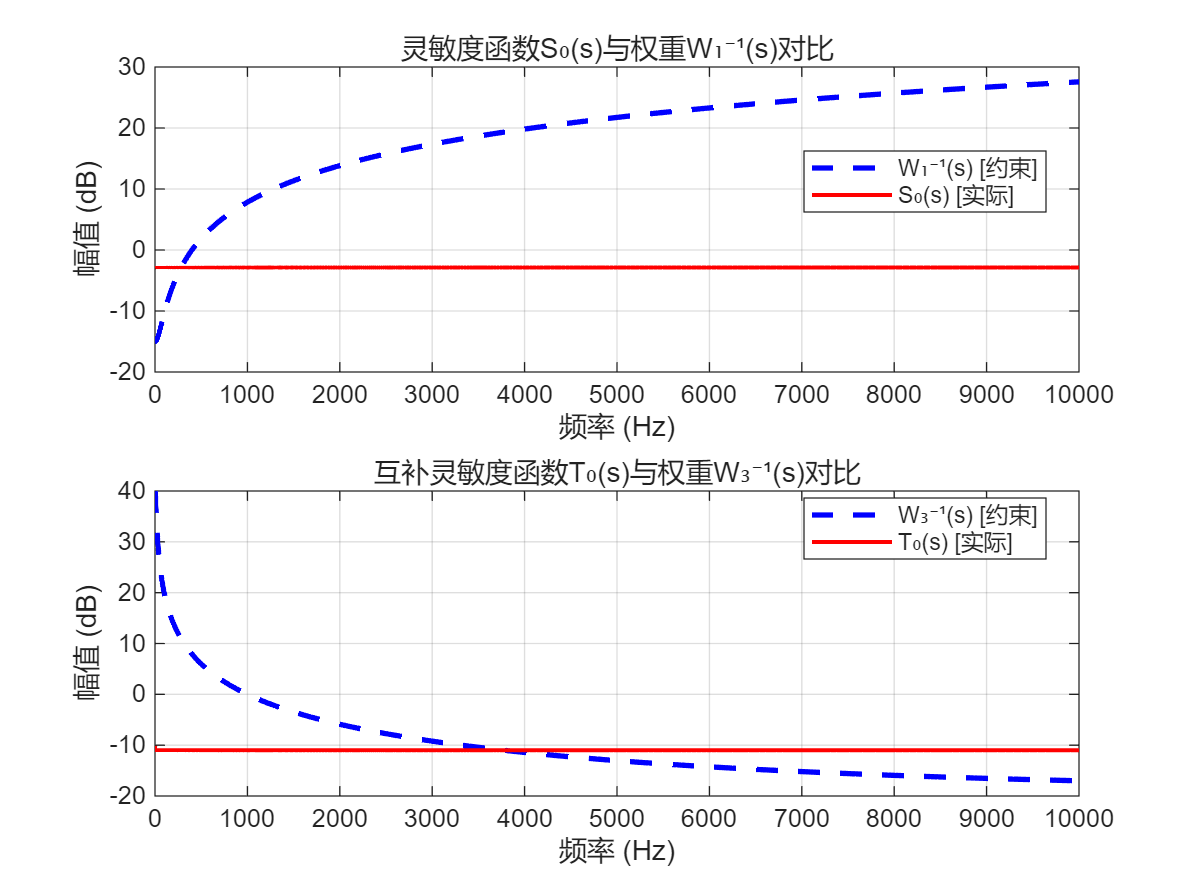


% 2. 灵敏度函数分析
S0 = feedback(1, P_tf);      % S = 1/(1+P*0) = 1
T0 = feedback(P_tf, 1);      % T = P/(1+P*0) = P
% 频率分析参数
f_hz = logspace(0, 4, 1000); % 1 Hz 到 10000 Hz
w_rad = 2*pi*f_hz;
% 绘制被控对象特性分析
plotSensitivityAnalysis(S0, T0, W1_inv, W3_inv, f_hz, w_rad, '被控对象固有特性分析', {'S₀(s)', 'T₀(s)'});

## 2 文中设计的固定控制器验证

文中提供了控制器计：$C\left(s\right)=$

% 根据论文Table II构建控制器
% poles_paper = [-2.0959, -1.6790, -0.8121, -0.0592+0.1973i, -0.0592-0.1973i] * 1e4;
% zeros_paper = [-3.4362, -0.1327+0.1302i, -0.1327-0.1302i, -0.1885, -0.0361] * 1e5;
% gain_paper = 0.1623;
% K_paper = zpk(zeros_paper, poles_paper, gain_paper);
% 或者根据传递函数构建控制器，本质上是一样的
K_paper = (0.7046*s^2 + 2.4466e5*s + 8.7447e8) / (s^2 + 1.1838e3*s + 4.2430e6) ...
    * (0.2303*s^2 + 6.1131e3*s + 7.9584e7) / (s^2 + 2.4912e4*s + 1.3636e8) ...
    * (s + 1.8851e4) / (s + 2.0959e4);
% 计算论文控制器的闭环系统
L_paper = P_tf * K_paper;
S_paper = feedback(1, L_paper);
T_paper = feedback(L_paper, 1);
% 检查闭环稳定性
if isstable(S_paper)
    fprintf('✓ 论文设计的闭环系统稳定\n');
else
    fprintf('❌ 论文设计的闭环系统不稳定\n');
end

❌ 论文设计的闭环系统不稳定


### 灵敏度函数分析

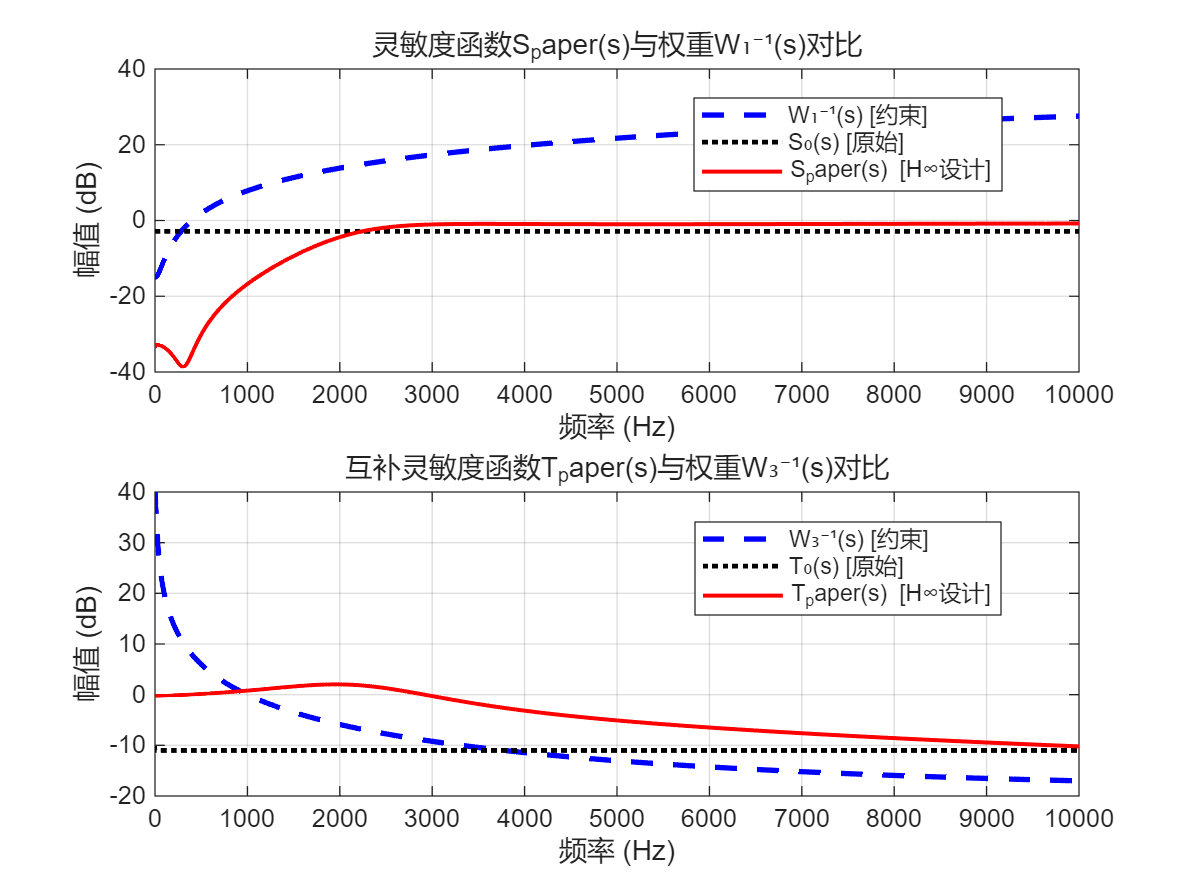

plotSensitivityAnalysis(S_paper, T_paper, W1_inv, W3_inv, f_hz, w_rad, ...
        '论文控制器验证结果 (Table II)', {'S_paper(s)', 'T_paper(s)'}, S0, T0);

### ANC仿真试验

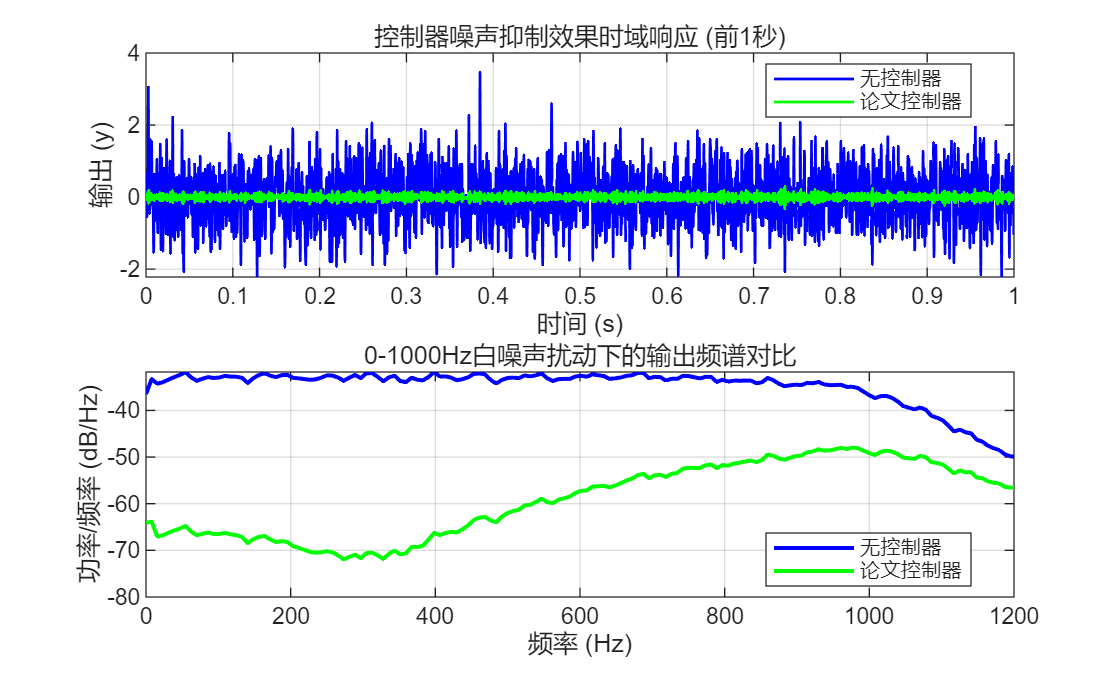

% 仿真参数
fs = 4000; % 采样频率 (Hz), 需大于 2*1000Hz
T = 5;     % 仿真时长 (s)
t = 0:1/fs:T-1/fs; % 时间向量

% 生成0-1000Hz的带限白噪声
d_raw = randn(size(t)); % 生成高斯白噪声
[b_filter, a_filter] = butter(6, 1000/(fs/2), 'low'); % 6阶巴特沃斯低通滤波器
d = filter(b_filter, a_filter, d_raw); % 滤波得到带限白噪声

% 离散化系统模型
P_d = c2d(P_tf, 1/fs, 'tustin');

% 仿真1: 无控制器 (开环响应, K=0, S=1)
% 此时输出 y = d
y_uncontrolled = d;

% 仿真2: 有H∞控制器 (闭环响应)
% 输出 y = S * d
S_paper_d = c2d(S_paper, 1/fs, 'tustin');
y_paper = lsim(S_paper_d, d, t);
% 计算功率谱密度 (PSD)
[psd_uncontrolled, f_psd] = pwelch(y_uncontrolled, hann(512), 256, 512, fs);
[psd_paper, ~] = pwelch(y_paper, hann(512), 256, 512, fs);

% 绘制时域响应
figure('Name', '控制器噪声抑制效果时频域分析');
subplot(2,1,1);
plot(t(1:4000), y_uncontrolled(1:4000), 'b-', 'LineWidth', 1.0, 'DisplayName', '无控制器');
hold on;
plot(t(1:4000), y_paper(1:4000), 'g-', 'LineWidth', 1.0, 'DisplayName', '论文控制器');
grid on;
xlabel('时间 (s)');
ylabel('输出 (y)');
title('控制器噪声抑制效果时域响应 (前1秒)');
legend('Location', 'best');

% 绘制频谱对比图
subplot(2,1,2);
plot(f_psd, 10*log10(psd_uncontrolled), 'b-', 'LineWidth', 1.5, 'DisplayName', '无控制器');
hold on;
plot(f_psd, 10*log10(psd_paper), 'g-', 'LineWidth', 1.5, 'DisplayName', '论文控制器');
grid on;
xlabel('频率 (Hz)');
ylabel('功率/频率 (dB/Hz)');
title('0-1000Hz白噪声扰动下的输出频谱对比');
legend('Location', 'best');
xlim([0 1200]); % 限制显示范围

### 音乐播放设置

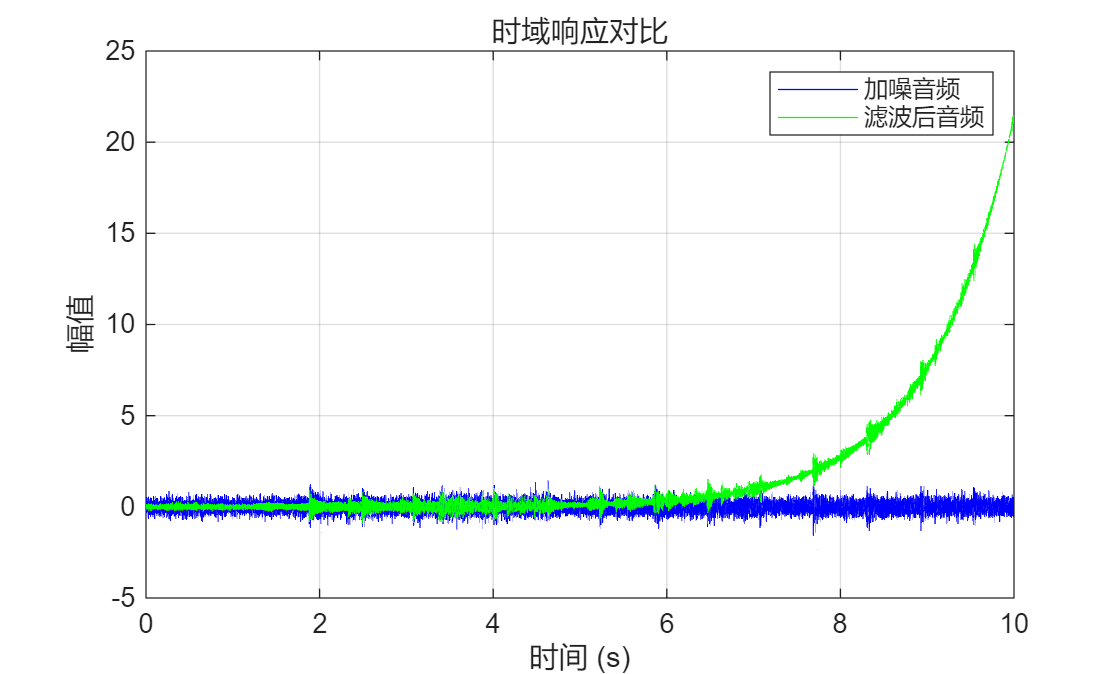

% 读取 mp3 文件
[audio_raw, Fs] = audioread('Alan Hawkshaw - Hawkwind and Fire.mp3'); % 替换为实际文件名
audio_len = length(audio_raw)/Fs;
T = 10; % 截取时长 (秒)
t_start = 2*Fs; % 截取中间10秒
audio = audio_raw(t_start+1:t_start+T*Fs);

% 生成0-1000Hz带限白噪声
d_raw = randn(size(audio));
[b_filter, a_filter] = butter(6, 1000/(Fs/2), 'low');
disturbance = filter(b_filter, a_filter, d_raw);

% 叠加噪声
audio_noisy = audio + disturbance;

% 播放原始和加噪音频
sound(audio_noisy, Fs); pause(T+1);

S_paper_d = c2d(S_paper, 1/Fs, 'tustin');
T_paper_d = c2d(T_paper, 1/Fs, 'tustin');
% 滤波（论文控制器作为前馈/滤波器示例，实际应为闭环灵敏度S）
y_filtered = lsim(S_paper_d, audio_noisy, (0:length(audio_noisy)-1)/Fs) + ...
    lsim(T_paper_d, audio, (0:length(audio_noisy)-1)/Fs);

% 播放滤波后音频
sound(y_filtered, Fs); pause(T+1);

% 频谱分析
[psd_noisy, f_psd] = pwelch(audio_noisy, hann(2048), 1024, 2048, Fs);
[psd_filtered, ~] = pwelch(y_filtered, hann(2048), 1024, 2048, Fs);

figure('Name', '控制器噪声抑制效果时频域分析');
plot((0:length(audio_noisy)-1)/Fs, audio_noisy, 'b-', 'DisplayName', '加噪音频');
hold on;
plot((0:length(y_filtered)-1)/Fs, y_filtered, 'g-', 'DisplayName', '滤波后音频');
xlabel('时间 (s)'); ylabel('幅值');
title('时域响应对比');
legend; grid on;

### 说明

- 控制器设计完全来自于论文中的说明，如何设计$W_1$和$W_3$求解得到控制器暂且不明。

- 为什么闭环系统不稳定，但是结果却没有发散？不是不发散，只是时候未到（主声源没有使得系统发散的频率，一旦出现就会发散）

- 如果控制器对宽频带白噪声实现了上述效果，音乐播放不会受影响吗？（互补灵敏度函数在特定频段内较平坦，保证音乐播放不受影响）

## 3 构建加权函数设计H∞控制器

H∞设计需要性能权重（如W1、W2、W3），可以根据实际需求设定。

根据文中图像逆向工程的结果为：


$$W_1^{-1}(s) =\frac{2.37 s^2 + 2500 s + 1.027e7}{  s^2 + 7969 s + 8.542e6} \qquad W_3^{-1}(s)=\frac{0.6554 s + 2592}{s + 3266}\\
S(s)=\frac{ 1.265 s^2 + 1380 s + 5.707e6}{s^2 + 4267 s + 8.01e6}\qquad T(s)=\frac{0.3975 s^2 + 3218 s + 1.659e6}{s^2 + 4439 s + 7.506e6}$$


% H∞综合
P_aug = augw(P_tf, W1, 1e-3, W3);
nmeas = 1; % 测量输出数量
ncon = 1;  % 控制输入数量
[K_hinf, ~, gamma] = hinfsyn(P_aug, nmeas, ncon);
% 权重函数设计分析与调试指导
analyzeWeightDesign(P_tf, W1, W3, K_hinf, gamma);


=== 权重函数设计分析与调试指导 ===
权重函数特性分析:
  W1低频增益(0.1 rad/s): 5.62 = 15.0 dB
  W1高频增益(1000 rad/s): 2.3253 = 7.3 dB
  W3低频增益(0.1 rad/s): 0.0100 = -40.0 dB
  W3高频增益(1000 rad/s): 0.16 = -15.9 dB

被控对象关键特性:
  ❌ 被控对象有2个不稳定极点，需要足够的控制带宽
     建议: 确保W1在不稳定极点频率附近有足够大的增益
  ⚠️  被控对象有2个右半平面零点，限制可达性能
     RHP零点频率: 1.03 0.00 rad/s
     建议: 在RHP零点频率附近适当放松W1约束

设计质量评估:
  H∞范数 γ = 65.2176 ✗ 需要改进
  控制器稳定性: ❌ 不稳定
     可能原因: W3高频滚降不足，或W1低频要求过于严格

具体调试建议:
  📝 gamma过大的可能原因和解决方案:
     - W1低频增益过大 → 适当减小W1的直流增益
     - W3高频增益不足 → 增大W3的高频增益
     - 缺少控制代价权重 → 在augw中添加小的W2(如1e-3)
  📝 控制器不稳定的可能原因和解决方案:
     - W3滚降速度不够快 → 增加W3分母的阶数或增大极点频率
     - W1和W3冲突 → 检查是否W1+W3在某频率点>1
     - 被控对象特殊结构 → 考虑添加预滤波器或改变控制结构

推荐的权重函数调整策略:
  🎯 W1设计原则:
     - 低频: 大增益(>10)确保扰动抑制
     - 中频: 平滑过渡
     - 高频: 小增益(<0.1)避免过度控制
  🎯 W3设计原则:
     - 低频: 小增益(<0.1)允许控制器有足够权威
     - 高频: 大增益(>1)确保鲁棒稳定性
     - 滚降: 至少40dB/dec确保控制器稳定

数值调整建议 (当前设计问题时):
  试试这些修改:
     W1_new = 0.7 * W1;  % 适当放松性能要求
     或者
     W3_new = 2 * W3;    % 增强鲁棒性要求
     或者
     P_aug = aug

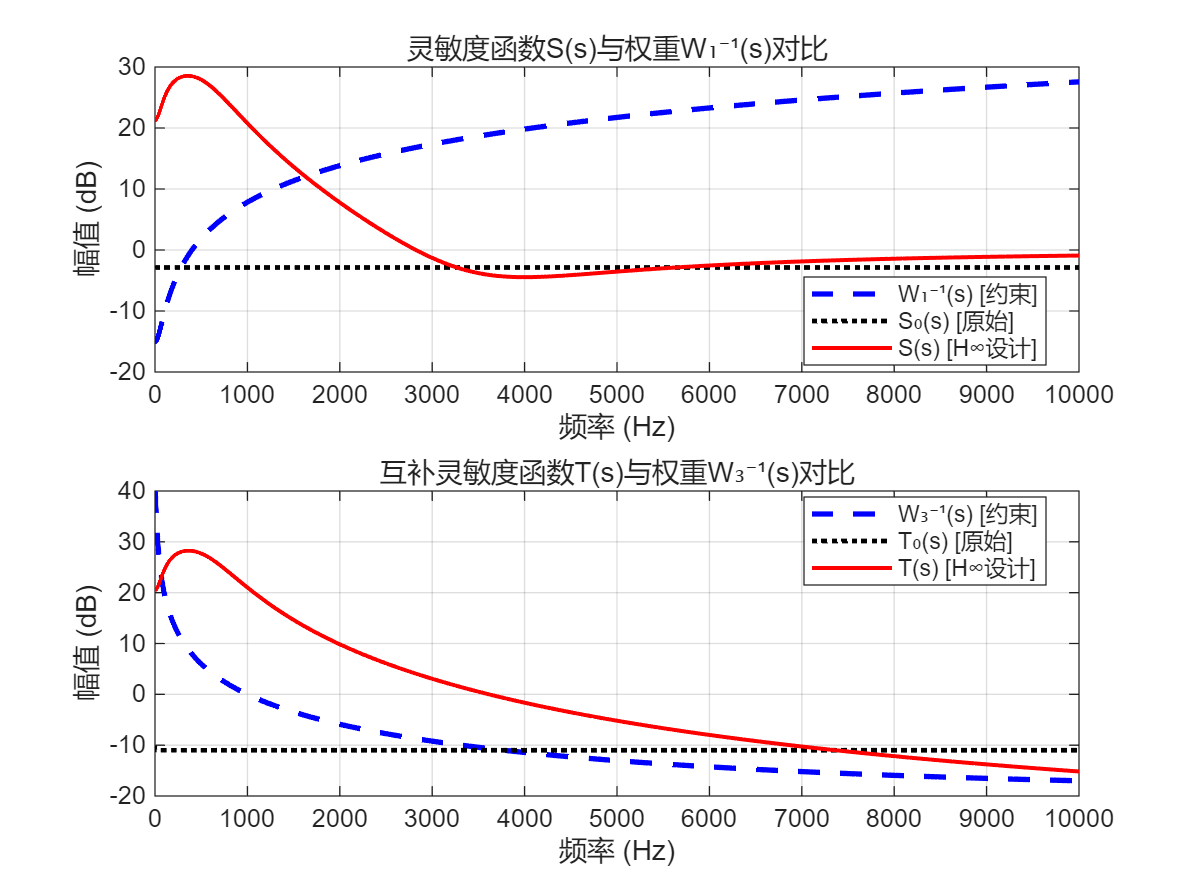

% 计算闭环传递函数
L = P_tf * tf(K_hinf); % 开环传递函数
S = feedback(1, L);    % S = 1/(1+L)
T = feedback(L, 1);    % T = L/(1+L)
% 绘制闭环系统性能分析，包含原始灵敏度函数对比
plotSensitivityAnalysis(S, T, W1_inv, W3_inv, f_hz, w_rad, ...
    sprintf('H∞控制器设计结果 (γ=%.3f)', gamma), {'S(s)', 'T(s)'}, S0, T0);

### ANC仿真试验

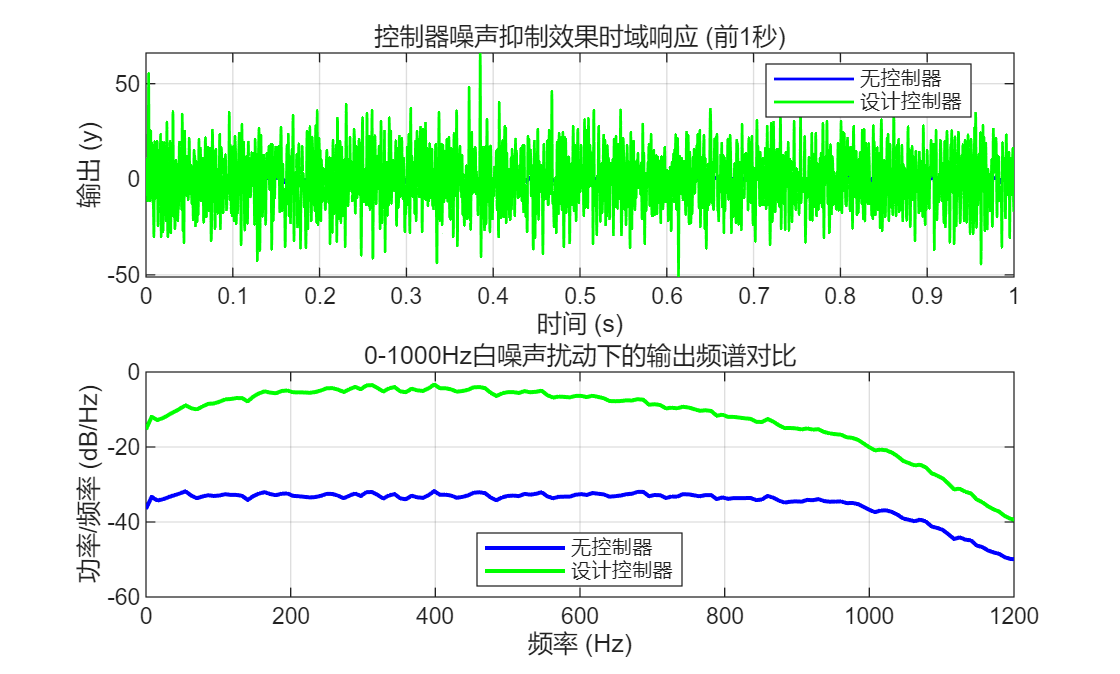

% 仿真1: 无控制器 (开环响应, K=0, S=1)
% 此时输出 y = d
y_uncontrolled = d;

% 仿真2: 有H∞控制器 (闭环响应)
% 输出 y = S * d
S_d = c2d(S, 1/fs, 'tustin');
y = lsim(S_d, d, t);
% 计算功率谱密度 (PSD)
[psd_uncontrolled, f_psd] = pwelch(y_uncontrolled, hann(512), 256, 512, fs);
[psd, ~] = pwelch(y, hann(512), 256, 512, fs);

% 绘制时域响应
figure('Name', '控制器噪声抑制效果时频域分析');
subplot(2,1,1);
plot(t(1:4000), y_uncontrolled(1:4000), 'b-', 'LineWidth', 1.0, 'DisplayName', '无控制器');
hold on;
plot(t(1:4000), y(1:4000), 'g-', 'LineWidth', 1.0, 'DisplayName', '设计控制器');
grid on;
xlabel('时间 (s)');
ylabel('输出 (y)');
title('控制器噪声抑制效果时域响应 (前1秒)');
legend('Location', 'best');

% 绘制频谱对比图
subplot(2,1,2);
plot(f_psd, 10*log10(psd_uncontrolled), 'b-', 'LineWidth', 1.5, 'DisplayName', '无控制器');
hold on;
plot(f_psd, 10*log10(psd), 'g-', 'LineWidth', 1.5, 'DisplayName', '设计控制器');
grid on;
xlabel('频率 (Hz)');
ylabel('功率/频率 (dB/Hz)');
title('0-1000Hz白噪声扰动下的输出频谱对比');
legend('Location', 'best');
xlim([0 1200]); % 限制显示范围

### 说明

- 由于所选择的$W_1$和$W_3$与论文设计不同/求解方法存在问题，暂未得到可靠的控制器设计；

- 为什么闭环系统不稳定，但是结果却没有发散？

## 附录：函数定义

%% 灵敏度函数绘制通用函数
function plotSensitivityAnalysis(S_func, T_func, W1_inv, W3_inv, f_hz, w_rad, fig_title, func_labels, S0_func, T0_func)
    % 计算频响数据
    [mag_W1inv, ~] = freqresp(W1_inv, w_rad);
    [mag_S, ~] = freqresp(S_func, w_rad);
    [mag_W3inv, ~] = freqresp(W3_inv, w_rad);
    [mag_T, ~] = freqresp(T_func, w_rad);
    
    % 转换为dB
    mag_W1inv_dB = 20*log10(squeeze(abs(mag_W1inv)));
    mag_S_dB = 20*log10(squeeze(abs(mag_S)));
    mag_W3inv_dB = 20*log10(squeeze(abs(mag_W3inv)));
    mag_T_dB = 20*log10(squeeze(abs(mag_T)));
    
    % 检查是否提供了参考灵敏度函数
    if nargin >= 10 && ~isempty(S0_func) && ~isempty(T0_func)
        [mag_S0, ~] = freqresp(S0_func, w_rad);
        [mag_T0, ~] = freqresp(T0_func, w_rad);
        mag_S0_dB = 20*log10(squeeze(abs(mag_S0)));
        mag_T0_dB = 20*log10(squeeze(abs(mag_T0)));
        show_reference = true;
    else
        show_reference = false;
    end
    
    % 创建图形
    figure('Name', fig_title, 'Position', [100, 100, 800, 600]);
    
    % 灵敏度函数对比
    subplot(2,1,1);
    plot(f_hz, mag_W1inv_dB, 'b--', 'LineWidth', 2); hold on;
    if show_reference
        plot(f_hz, mag_S0_dB, 'k:', 'LineWidth', 1.8, 'DisplayName', 'S₀(s) [原始]');
    end
    plot(f_hz, mag_S_dB, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('频率 (Hz)');
    ylabel('幅值 (dB)');
    title(['灵敏度函数', func_labels{1}, '与权重W₁⁻¹(s)对比']);
    if show_reference
        legend({'W₁⁻¹(s) [约束]', 'S₀(s) [原始]', [func_labels{1}, ' [H∞设计]']}, 'Location', 'best');
    else
        legend({'W₁⁻¹(s) [约束]', [func_labels{1}, ' [实际]']}, 'Location', 'best');
    end
    
    % 互补灵敏度函数对比
    subplot(2,1,2);
    plot(f_hz, mag_W3inv_dB, 'b--', 'LineWidth', 2); hold on;
    if show_reference
        plot(f_hz, mag_T0_dB, 'k:', 'LineWidth', 1.8, 'DisplayName', 'T₀(s) [原始]');
    end
    plot(f_hz, mag_T_dB, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('频率 (Hz)');
    ylabel('幅值 (dB)');
    title(['互补灵敏度函数', func_labels{2}, '与权重W₃⁻¹(s)对比']);
    if show_reference
        legend({'W₃⁻¹(s) [约束]', 'T₀(s) [原始]', [func_labels{2}, ' [H∞设计]']}, 'Location', 'best');
    else
        legend({'W₃⁻¹(s) [约束]', [func_labels{2}, ' [实际]']}, 'Location', 'best');
    end
end

%% 权重函数设计分析与调试指导
function analyzeWeightDesign(P, W1, W3, K, gamma)
    fprintf('\n=== 权重函数设计分析与调试指导 ===\n');
    
    % 1. 检查权重函数的基本特性
    fprintf('权重函数特性分析:\n');
    
    % W1的低频和高频增益
    w_low = 0.1;   % 低频点
    w_high = 1000; % 高频点
    W1_dc = abs(evalfr(W1, 1j*w_low));
    W1_hf = abs(evalfr(W1, 1j*w_high));
    fprintf('  W1低频增益(%.1f rad/s): %.2f = %.1f dB\n', w_low, W1_dc, 20*log10(W1_dc));
    fprintf('  W1高频增益(%.0f rad/s): %.4f = %.1f dB\n', w_high, W1_hf, 20*log10(W1_hf));
    
    % W3的低频和高频增益  
    W3_dc = abs(evalfr(W3, 1j*w_low));
    W3_hf = abs(evalfr(W3, 1j*w_high));
    fprintf('  W3低频增益(%.1f rad/s): %.4f = %.1f dB\n', w_low, W3_dc, 20*log10(W3_dc));
    fprintf('  W3高频增益(%.0f rad/s): %.2f = %.1f dB\n', w_high, W3_hf, 20*log10(W3_hf));
    
    % 2. 检查被控对象的关键特性
    fprintf('\n被控对象关键特性:\n');
    P_poles = pole(P);
    P_zeros = zero(P);
    unstable_poles = P_poles(real(P_poles) >= 0);
    rhp_zeros = P_zeros(real(P_zeros) > 0);
    
    if ~isempty(unstable_poles)
        fprintf('  ❌ 被控对象有%d个不稳定极点，需要足够的控制带宽\n', length(unstable_poles));
        fprintf('     建议: 确保W1在不稳定极点频率附近有足够大的增益\n');
    end
    
    if ~isempty(rhp_zeros)
        fprintf('  ⚠️  被控对象有%d个右半平面零点，限制可达性能\n', length(rhp_zeros));
        rhp_freq = abs(rhp_zeros);
        fprintf('     RHP零点频率: ');
        for i = 1:length(rhp_freq)
            fprintf('%.2f ', rhp_freq(i));
        end
        fprintf('rad/s\n');
        fprintf('     建议: 在RHP零点频率附近适当放松W1约束\n');
    end
    
    % 3. 设计质量评估
    fprintf('\n设计质量评估:\n');
    fprintf('  H∞范数 γ = %.4f', gamma);
    if gamma < 1
        fprintf(' ✓ 优秀\n');
    elseif gamma < 1.5
        fprintf(' △ 可接受\n');
    else
        fprintf(' ✗ 需要改进\n');
    end
    
    % 控制器稳定性
    if isstable(K)
        fprintf('  控制器稳定性: ✓ 稳定\n');
    else
        fprintf('  控制器稳定性: ❌ 不稳定\n');
        fprintf('     可能原因: W3高频滚降不足，或W1低频要求过于严格\n');
    end
    
    % 4. 具体调试建议
    fprintf('\n具体调试建议:\n');
    
    if gamma >= 1.5
        fprintf('  📝 gamma过大的可能原因和解决方案:\n');
        fprintf('     - W1低频增益过大 → 适当减小W1的直流增益\n');
        fprintf('     - W3高频增益不足 → 增大W3的高频增益\n');
        fprintf('     - 缺少控制代价权重 → 在augw中添加小的W2(如1e-3)\n');
    end
    
    if ~isstable(K)
        fprintf('  📝 控制器不稳定的可能原因和解决方案:\n');
        fprintf('     - W3滚降速度不够快 → 增加W3分母的阶数或增大极点频率\n');
        fprintf('     - W1和W3冲突 → 检查是否W1+W3在某频率点>1\n');
        fprintf('     - 被控对象特殊结构 → 考虑添加预滤波器或改变控制结构\n');
    end
    
    % 5. 推荐的权重函数调整策略
    fprintf('\n推荐的权重函数调整策略:\n');
    fprintf('  🎯 W1设计原则:\n');
    fprintf('     - 低频: 大增益(>10)确保扰动抑制\n');
    fprintf('     - 中频: 平滑过渡\n');
    fprintf('     - 高频: 小增益(<0.1)避免过度控制\n');
    fprintf('  🎯 W3设计原则:\n');
    fprintf('     - 低频: 小增益(<0.1)允许控制器有足够权威\n');
    fprintf('     - 高频: 大增益(>1)确保鲁棒稳定性\n');
    fprintf('     - 滚降: 至少40dB/dec确保控制器稳定\n');
    
    % 6. 数值建议
    fprintf('\n数值调整建议 (当前设计问题时):\n');
    if gamma > 1.2 || ~isstable(K)
        fprintf('  试试这些修改:\n');
        fprintf('     W1_new = 0.7 * W1;  %% 适当放松性能要求\n');
        fprintf('     或者\n');
        fprintf('     W3_new = 2 * W3;    %% 增强鲁棒性要求\n');
        fprintf('     或者\n');
        fprintf('     P_aug = augw(P, W1, 1e-2, W3); %% 添加控制代价\n');
    end
end